# EXERCISE #4 : Bluetooth LE and WLAN Coexistence 

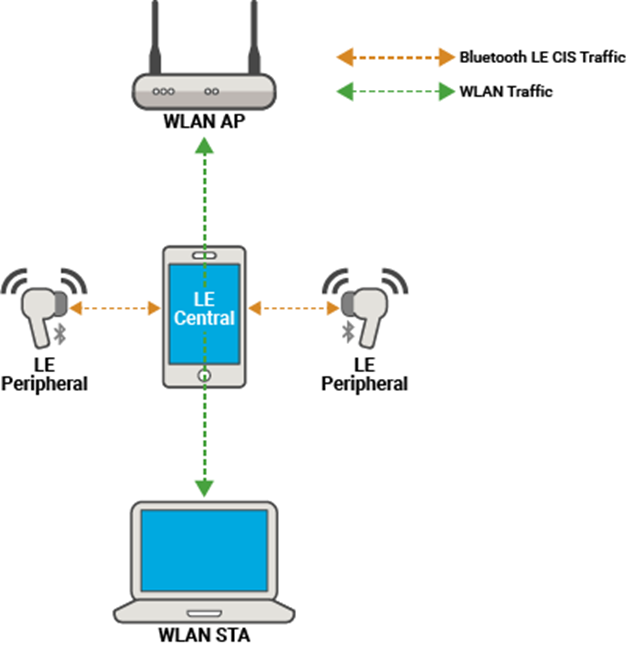

**In this exercise, you will:**

- Model a Bluetooth LE network and a WLAN network in close proximity.

- Learn the workflow to mitigate interference using a non-collaborative approach.

- Use Adaptive Frequency Hopping (AFH) to classify good and bad Bluetooth LE channels.

all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities
wirelessnetworkSupportPackageCheck
rng(1,"twister");
networkSimulator = wirelessNetworkSimulator.init;
simulationTime = 2;

#### Create a Bluetooth LE node, specifying the role as `"central"`.

source = bluetoothLENode("central", ...
    "Name","Central", ...
    Position=[0 0 0], ...
    TransmitterPower=-20, ...
    TransmitterGain=0, ...
    ReceiverGain=0, ...
    ReceiverSensitivity=-100);  

#### Create Bluetooth LE nodes, specifying the role as `"peripheral"` and name as leftsink 

leftSink = bluetoothLENode("Peripheral", ...
    Position=[7 0 0], ...
    Name="leftsink", ...
    TransmitterPower=-20, ...
    TransmitterGain=0, ...
    ReceiverGain=0, ...
    ReceiverSensitivity=-100);

#### Create Bluetooth LE nodes, specifying the role as `"peripher`al" and name as rightsink 

rightSink = bluetoothLENode("Peripheral", ...
    Position=[7.2 0 0], ...
    Name="rightsink", ...
    TransmitterPower=-20, ...
    TransmitterGain=0, ...
    ReceiverGain=0, ...
    ReceiverSensitivity=-100);

To set the timing of ACL and CIS events, specify these values.

- Connection interval 

- Isochronous (ISO) interval 

isoInterval = 0.050;        % In seconds
connectionInterval = 0.10;  % In seconds
phymode = "LE2M";

####  Create a Bluetooth LE CIS configuration 

cfgCIS = bluetoothLECISConfig(ISOInterval=isoInterval, ...
    NumSubevents=9, ...
    BurstNumber=9, ...
    SubInterval= 2.5e-3,...
    MaxPDU= 251,...
    FlushTimeout= 1,...
    TMSS= 150e-6,...
    TIFS= 150e-6,... 
    CISArrangement="sequential");
len = subeventLength(cfgCIS,phymode)

#### Create a Bluetooth LE connection configuration 

[Instant Offset](https://www.mathworks.com/help/bluetooth/ref/bluetoothleconnectionconfig.html#mw_cab91f30-3ec5-4d1f-a371-5c4fda434b61)

cfgConnection = bluetoothLEConnectionConfig(ConnectionInterval=connectionInterval, ...
    ActivePeriod=0.001, ...
    MaxPDU=27, ...
    PHYMode=phymode, ...
    InstantOffset=6);
bleMinActivePeriod(cfgConnection.MaxPDU,phymode)

#### Configure the ACL and CIS connection between the source and the left sink

cfgConnection.AccessAddress = "5DA44270";
cfgConnection.ConnectionOffset = 0; 
    [leftConnCfg,leftCISCfg] = configureConnection(cfgConnection, ...
    source, ...
    leftSink, ...
    CISConfig=cfgCIS); 

####  Configure the ACL and CIS connection between the source and the right sink

cfgConnection.AccessAddress = "5DA44271";
cfgConnection.ConnectionOffset = 0.05; % In seconds
  
[rightConnCfg,rightCISCfg] = configureConnection(cfgConnection, ...
    source, ...
    rightSink, ...
    CISConfig=cfgCIS);

#### Add the source and sink nodes to the wireless network simulator.

nodes = [source leftSink rightSink];
peripheralNodes = [leftSink rightSink];
addNodes(networkSimulator,nodes);

#### Add Audio Traffic

dataRate = 320;
leftSinkTraffic = networkTrafficOnOff(DataRate=dataRate,PacketSize=cfgCIS.MaxPDU,GeneratePacket=true,OnTime=Inf,OffTime=0);
rightSinkTraffic = networkTrafficOnOff(DataRate=dataRate,PacketSize=cfgCIS.MaxPDU,GeneratePacket=true,OnTime=Inf,OffTime=0);
plotTrafficPattern(simulationTime,rightSinkTraffic)
addTrafficSource(source,leftSinkTraffic,DestinationNode=leftSink,CISConfig=leftCISCfg);
addTrafficSource(source,rightSinkTraffic,DestinationNode=rightSink,CISConfig=rightCISCfg);

#### Add Custom Path Loss Model

cfgPathloss = bluetoothPathLossConfig(Environment="Home");
pathlossHandle = @(rxInfo,txData) updatePathLoss(rxInfo,txData,cfgPathloss); % Path loss function
addChannelModel(networkSimulator,pathlossHandle);

#### Add the WLAN BSS

enableWLANNetwork = true;
if enableWLANNetwork
    % Set WLAN band and channel
    bandAndChannel = [2.4 7];
    % Configure Access Point (AP)
    apDeviceConfig = wlanDeviceConfig(Mode="AP",BandAndChannel=bandAndChannel,TransmitPower=20,InterferenceModeling="overlapping-adjacent-channel");
    % Configure Station (STA)
    staDeviceConfig = wlanDeviceConfig(Mode="STA",BandAndChannel=bandAndChannel,TransmitPower=20,InterferenceModeling="overlapping-adjacent-channel");
    % Create an AP with the specified configuration
    wlanAPNode = wlanNode(DeviceConfig=apDeviceConfig,Name="WLAN AP",Position=[3.5 0 0],MACFrameAbstraction=false,PHYAbstractionMethod="none");
    % Create an STA with the specified configuration
    wlanSTANode = wlanNode(DeviceConfig=staDeviceConfig,Name="WLAN STA",Position=[5.5 0 0], MACFrameAbstraction=false,PHYAbstractionMethod="none");
    % Set up the WLAN network
    associateStations(wlanAPNode,wlanSTANode,BandAndChannel=bandAndChannel);
    % Add AP-to-STA traffic
    ap2staTraffic = networkTrafficOnOff(OnTime=Inf,OffTime=0,DataRate=35000,PacketSize=200);
    addTrafficSource(wlanAPNode,ap2staTraffic,DestinationNode=wlanSTANode);
    % Add STA-to-AP traffic
    sta2apTraffic = networkTrafficOnOff(OnTime=Inf,OffTime=0,DataRate=35000,PacketSize=200);
    addTrafficSource(wlanSTANode,sta2apTraffic,DestinationNode=wlanAPNode);
    % Add WLAN nodes to the network simulator
    wlanNodes = [wlanAPNode wlanSTANode];
    addNodes(networkSimulator,wlanNodes)
end

#### Enable Adaptive Frequency Hopping (AFH) in the Bluetooth LE network

useAdaptiveFrequencyHopping = false;
if useAdaptiveFrequencyHopping
   for i = 1:length(peripheralNodes)
        classifierObj = helperBluetoothChannelClassification(...
            source,peripheralNodes(i),PERThreshold=30);
        classifyFcn = @(varargin) classifierObj.classifyChannels;
        userData = [];
        callAt = 0;
        periodicity = 125e-3;
        scheduleAction(networkSimulator,classifyFcn,userData,callAt,periodicity);
   end
    coexistenceVisualization = helperVisualizeCoexistence(simulationTime,nodes);
end

# Task #1/2  Scheduling an action for the simulator to perform  

useBLEChannelUpdate = false;
if useBLEChannelUpdate
startTime   = 0.01;
userData = struct( ...
    ActionType  = "oneTime", ...
    bleNodes   = nodes, ...
    wifiNodes   = wlanNodes, ...
    Simulator   = networkSimulator);

% ActionType can be Periodic, TimeAdvance, OneTime

% Use scheduleAction() function to get interruption every time the engine advances from one step to the next
% Note : name the callback function "@updateBLEChannel"
% Set the first argument to the node networkSimulator object 
% Set the other arguments in the following sequence  
% @updateBLEChannel,userData,startTime
% Hint: Click the link below and see the "Syntax" section.

[Help on sheduling action ](https://www.mathworks.com/help/releases/R2024b/comm/ref/wirelessnetworksimulator.scheduleaction.html)

% Enter code below

end 

#### Visualize Packet Transitions

helperPlotPacketTransitions(networkSimulator.Nodes,simulationTime,FrequencyPlotFlag=true);

#### **Simulation and Results**

run(networkSimulator,simulationTime);

Retrieve the statistics of all the nodes. For more information about Bluetooth LE node statistics, see [Bluetooth LE Statistics](docid:bluetooth_ug#mw_675e1436-48b0-41db-bba4-5f34fb750a31).

sourceStats = nodes(1).statistics;
leftSinkStats = nodes(2).statistics;
rightSinkStats = nodes(3).statistics;
leftSinkRxThroughtput = (leftSinkStats.LL.CISStatistics.ReceivedBytes*8)/(simulationTime*1000);
rightSinkRxThroughtput = (leftSinkStats.LL.CISStatistics.ReceivedBytes*8)/(simulationTime*1000);
fprintf(['Left Sink Rx Throughput: %f kbps\n ' ...
    'Right Sink Rx Throughput: %f kbps\n ' ...
    ], ...
    leftSinkRxThroughtput , ...
    rightSinkRxThroughtput);

# Task #2/2  Update Bluetooth LE channels between Source and Sinks

[Help on updating BLE channel map](https://in.mathworks.com/help/bluetooth/ref/bluetoothlenode.updatechannellist.html)

function updateBLEChannel(~,userData)
source = userData.bleNodes(1);
leftsink = userData.bleNodes(2);
rightsink =userData.bleNodes(3);
wlanBand = userData.wifiNodes(1).DeviceConfig.BandAndChannel(1);
wlanChannel = userData.wifiNodes(1).DeviceConfig.BandAndChannel(2);
wlanBW = userData.wifiNodes(1).DeviceConfig.ChannelBandwidth;
wlanCenter  = wlanChannelFrequency(wlanChannel,wlanBand);

numBLE = 37;   % BLE Data channels
bleBW  = 2e6;    % MHz
overlapResults = zeros(1, numBLE);
wlanBand = [wlanCenter - wlanBW/2, wlanCenter + wlanBW/2];
BleDataChannelFrequencies = [2404:2:2424 2428:2:2478]*1e6;
for ch = 0:numBLE-1
    bleFreq =BleDataChannelFrequencies(ch+1);  % center frequency in MHz
    bleBand = [bleFreq - bleBW/2, bleFreq + bleBW/2];    
    % overlap calculation
    overlap = max(0, min(bleBand(2), wlanBand(2)) - max(bleBand(1), wlanBand(1)));
    overlapResults(ch+1) = overlap;
    
end
goodChannels = find(overlapResults == 0) -1;
goodChannels = goodChannels(goodChannels <= 36);
if userData.ActionType == "oneTime"
   
    % Use updateChannelList() function to set BLE network to hop on good channles
    % Set the first argument to the central node object: source
    % Set the other arguments in the following sequence
    % goodChannels,DestinationNode=leftsink
    % Hint: Click the link above and see the "Syntax" section.
    % Enter code below

    % Use updateChannelList() function to set BLE network to hop on good channles
    % Set the first argument to the central node object: source
    % Set the other arguments in the following sequence
    % goodChannels,DestinationNode=rightsink
    % Hint: Click the link above and see the "Syntax" section.
    % Enter code below
   
end
end


*Copyright 2023-2024 The MathWorks, Inc.*